# Panda APF Secondary

clear

## Grid

grid = OctoGrid(2,2,2,100);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

## Generate a list of transformations

transformations_list = getPartialTransformationsListPanda('points_per_segment', 5*[1 1 1 1 1 1 1])

transformations_list = 1×35 struct array with fields:
    tree
    segm_num
    segm_part


## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

## Calculate field

% Attractive
[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);

% Repulsive
kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

[grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

% Total
Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;

## Calculate APF Value in i-th point

% robot joints configuration
joints = [0.1520
   -0.3747
    0.2588
   -2.2680
    0.0899
    1.8967
    0.3447];

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

% calculate APF value and get T matrix
[value, transform] = getPartialAPFValueRobotTreePoint(grid_total_field, grid.resolution, transformations_list(1).tree, Tbase, joints)

value = 6.0412

transform =     0.9885   -0.0000   -0.1514    1.0000
    0.1514    0.0000    0.9885    1.0000
         0   -1.0000    0.0000    0.0666
         0         0         0    1.0000


## Draw Robot 

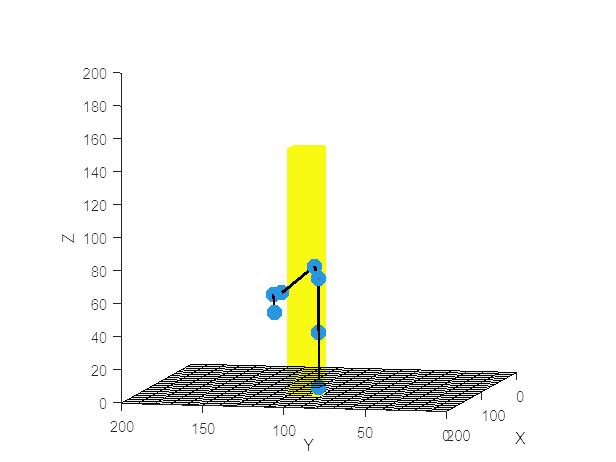

% calculate robot poses for display
[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

% display grid
grid.showGridVol3D(grid.grid,'floor',true,'height',false)
hold on
axis equal

% display robot
showPanda(robot_transforms,grid.resolution)
hold off

## Calculate APF Gradient Value in i-th point